clear
close all
clf

load EyesTestData.mat
load NotEyesTestData.mat

load eyeModelCompactKernel8Tree.mat

image = EyesTestData(:, :, :, 1);
imageGray = rgb2gray(image);
hog = extractHOGFeatures(imageGray, 'CellSize', [8 8]);

mida_eyes = size(EyesTestData);
test_data_eyes = zeros(mida_eyes(4), width(hog));
for i=1:mida_eyes(4)
    image = EyesTestData(:, :, :, i);
    imageGray = rgb2gray(image);
    test_data_eyes(i, :) = extractHOGFeatures(imageGray, 'CellSize', [8 8]);
end

mida_not_eyes = size(NotEyesTestData);
test_data_not_eyes = zeros(mida_not_eyes(4), width(hog));
for i=1:mida_not_eyes(4)
    if (mod(i, 500) == 0)
        i
    end
    image = NotEyesTestData(:, :, :, i);
    imageGray = rgb2gray(image);
    test_data_not_eyes(i, :) = extractHOGFeatures(imageGray, 'CellSize', [8 8]);
end

i = 500

i = 1000


test_data = [test_data_eyes, ones(mida_eyes(4), 1); test_data_not_eyes, zeros(mida_not_eyes(4), 1)];
T = array2table(test_data);

titulos = strings(width(hog), 1);
for i = 1: width(hog)
    titulos(i) = "Atributo " + int2str(i);
end

titulos = [titulos; "Clase"];

T.Properties.VariableNames = titulos;

should = T.Clase;
yfit = eyeModelCompact.predictFcn(T);

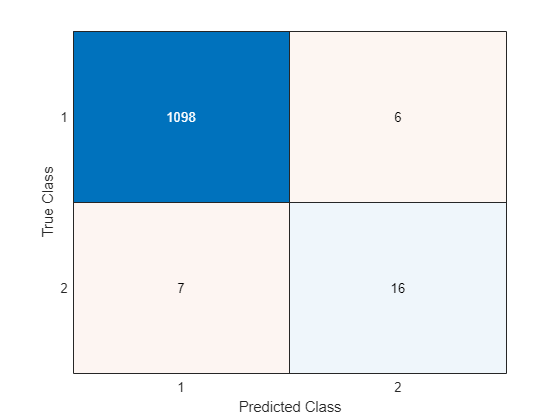

hola =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [1 2]

  Show all properties


hola = confusionchart(confusionmat(should, yfit))